# Noise

## White Noise

White noise is important for random signal modelling. 

`INSIGHT`*:* we can use white noise to find the impulse response of a system because the autocorrelation of white noise is the same the delta signal.

### Generating a realisation of the white Gaussian noise in MATLAB

To generate $N$ random numbers for a Gaussian random variable with mean $\mu$ and variance $\sigma^2$ we use following MATLAB functions

clear variables;

N = 1000;
variance = 25;
std_dev = sqrt(variance);
mu = 500;
w = std_dev.*randn(N,1) + mu;

% Calculate the sample mean, standard deviation, and variance.
stats = [mean(w) std(w) var(w)]

stats =   499.9186    4.9628   24.6291


The mean and variance are not 500 and 25 exactly because they are calculated from a sampling of the distribution.

Suppose we have a random process that produces perfect random noise. Let $w\left(n\right)$ be a random signal from this process.

### Expected value of White Noise

The** expected value** of the signal is zero because there are no patterns in white noise:

    
$$E\left\lbrack w\left(n\right)\right\rbrack =0$$


### Autocorrelation of White Noise

The **autocorrelation of white noise** generates one peak at $\ell =0$ because that is the only time when there is any correlation of the signal. One peak at $\ell =0$ can be modelled by delta signal:

        
$$r_{\textrm{ww}} \left(\ell \right)=E\left\lbrack w\left(n\right)w\left(n-\ell \right)\right\rbrack =\sigma_w^2 \delta \left(\ell \right)$$


where $\sigma_w^2$ is the variance of the signal.

### Variance of white noise

The variance of a random variable $X$ is defined by:

        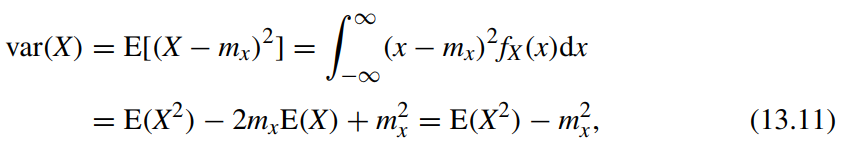

The variance of white noise which can be computed as follow:

        $\begin{array}{l}
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack -E{\left\lbrack w\left(n\right)\right\rbrack }^2 \\
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack -0\\
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack 
\end{array}$     (by definition $E\left\lbrack w\left(n\right)\right\rbrack =0$)

### Cross-correlation of two uncorrelated noise processes

Let $v\left(n\right)$ and $w\left(n\right)$ be **two uncorrelated white noise **processes with variance $\sigma_v^2 =0\ldotp 49$ and $\sigma_w^2 =1$. The cross-correlation between these processes is:

        
$$r_{\mathrm{vw}} \left(\ell \right)=0$$


### **Power spectral density of white noise**

The power spectral density of white noise is constant which means that we have the same power across all frequencies. This signal is called white noise because the power is equally distributed across the entire spectrum.

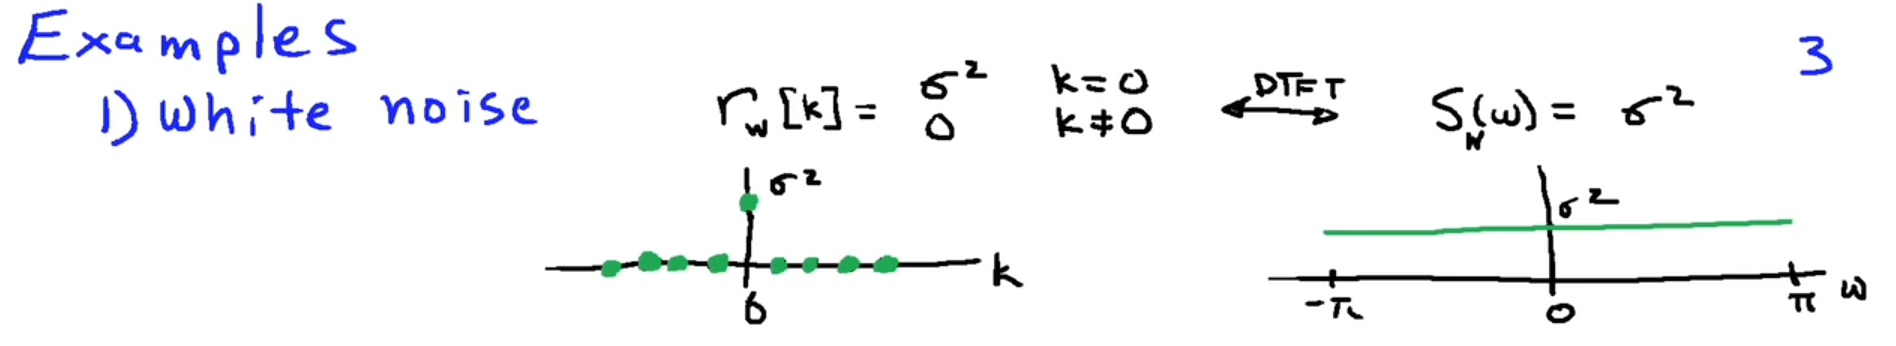

The **power spectral density of white noise** is:

        
$$S_w \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{ww}} \left(\ell \right)e^{-j\omega \ell }$$


        
$$S_w \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } \sigma_w^2 \delta \left(\ell \right)e^{-j\omega \ell }$$


All terms where $\ell \not= 0$ become zero so we left with one term when $\ell =0$

        
$$S_w \left(\omega \right)=\sigma_w^2 \delta \left(0\right)e^{-j\omega \cdot 0}$$


        
$$S_w \left(\omega \right)=\sigma_w^2 \cdot 1\cdot 1$$


        
$$S_w \left(\omega \right)=\sigma_w^2$$


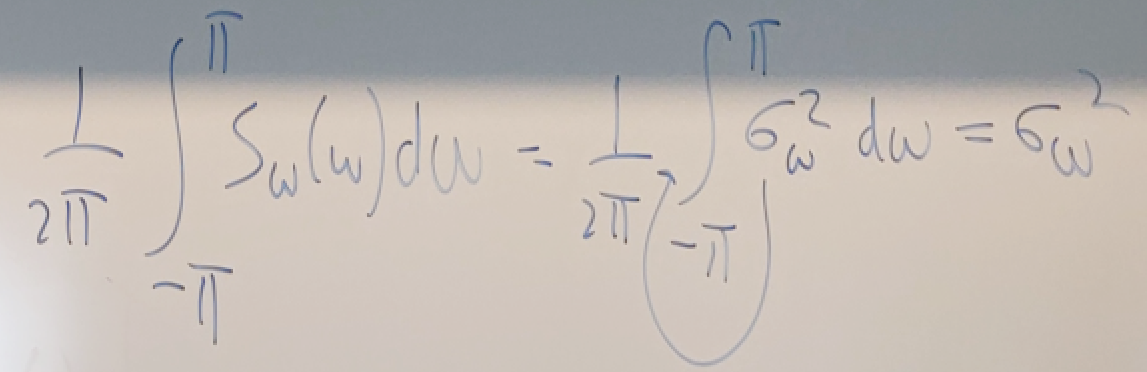

## Coloured Noise

### How to generate coloured noise?

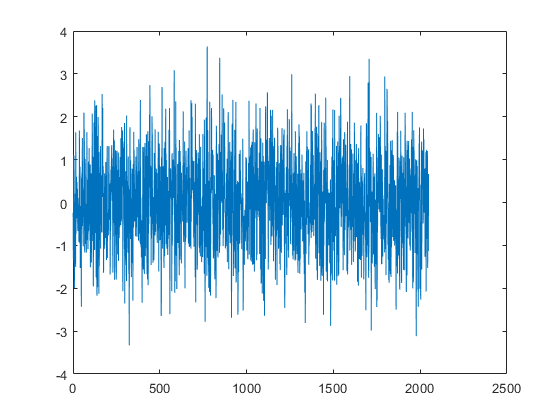

N = 2048;

% Slight coloured noise
x1 = step(dsp.ColoredNoise('InverseFrequencyPower', 0.1, 'SamplesPerFrame', N));
plot(x1);

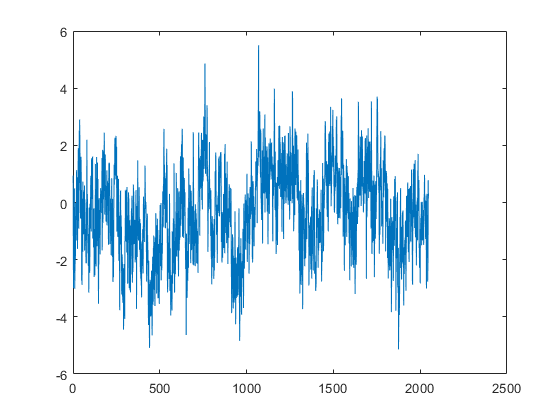

% Very coloured noise (Pink noise)
x1 = step(dsp.ColoredNoise('InverseFrequencyPower', 1, 'SamplesPerFrame', N));
plot(x1);

## Problems

### Quiz: is white noise cubed also a white noise?

clear variables;

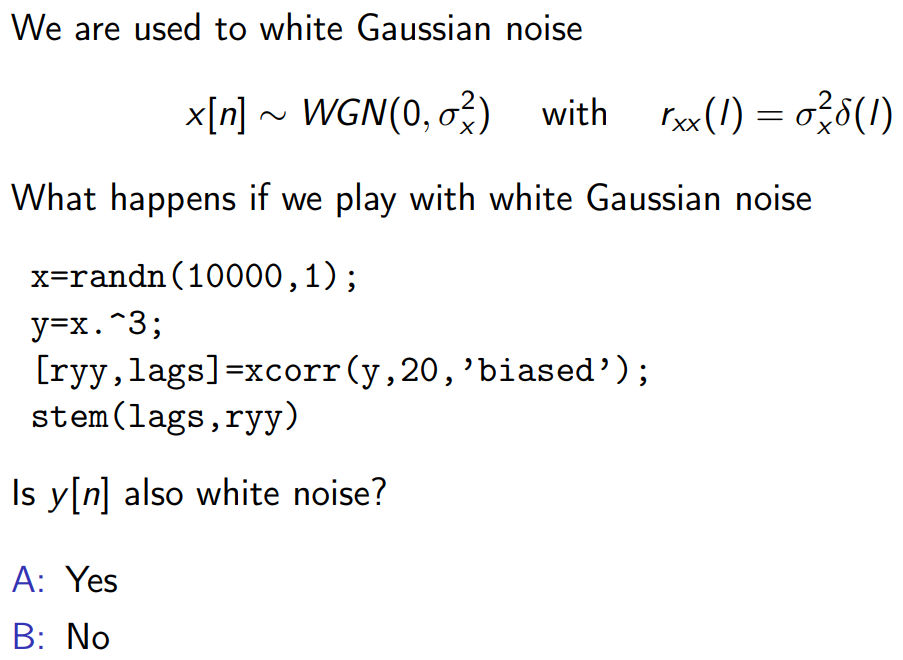

So the question is this: suppose we have a white noise signal $x\left(n\right)$. If we take each element of this signal and cube it, would the resulting signal also be white noise?

The answer is **yes**! The output is also white noise because we are not introducing any correlation between different samples. 

Let us prove it in MATLAB.

If we plot the autocorrelation of white noise, we should observe a signal similar to delta signal with amplitude of $\sigma_x^2$ because:

    if $x\left(n\right)~\mathrm{WGN}\left(0,\sigma_x^2 \right)$ then $r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)$

First, we plot $r_{\mathrm{xx}} \left(\ell \right)$

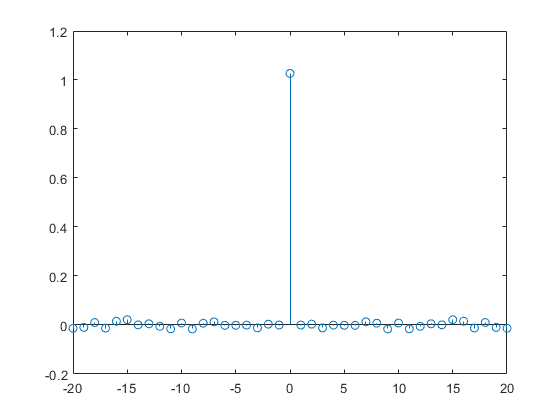

N = 10000;
n = [1:N];
x = wgn(N,1,0);

[r_xx, lags] = xcorr(x, 20, 'biased');
stem(lags, r_xx);

This looks like what have expected.

Now, let us plot the autocorrelation of $y\left(n\right)=x^3 \left(n\right)$

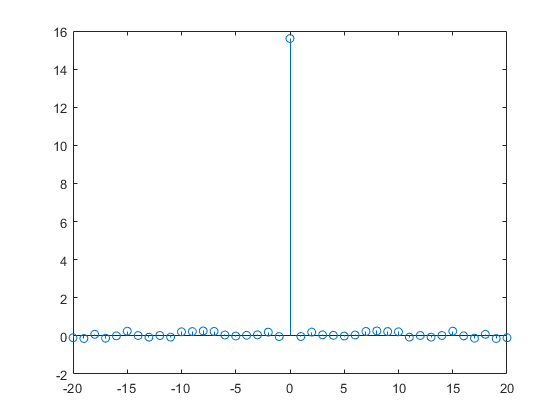

y = x.^3;
[r_yy, lags] = xcorr(y, 20, 'biased');
stem(lags, r_yy);

This proves that the answer to the quiz is Yes!

`INSIGHT`***: ***Noise does not necessarily have to be Gaussian in order to be white. White noise can have any probability density function. Noise is said to be white when there is no correlation between samples.

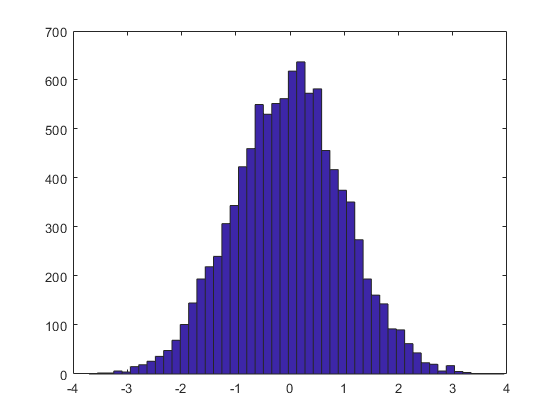

hist(x, 50)

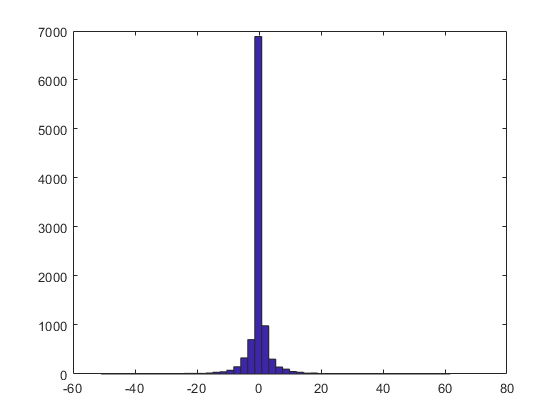

hist(y, 50)

### Quiz: is a sequence drawn from a probability distribution white noise?

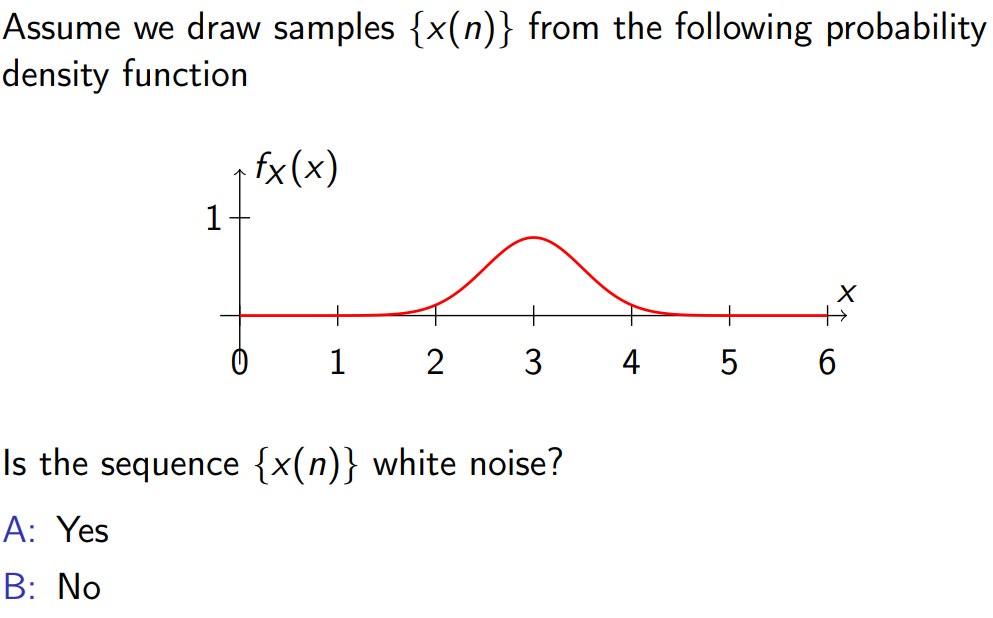

Answer: Yes!